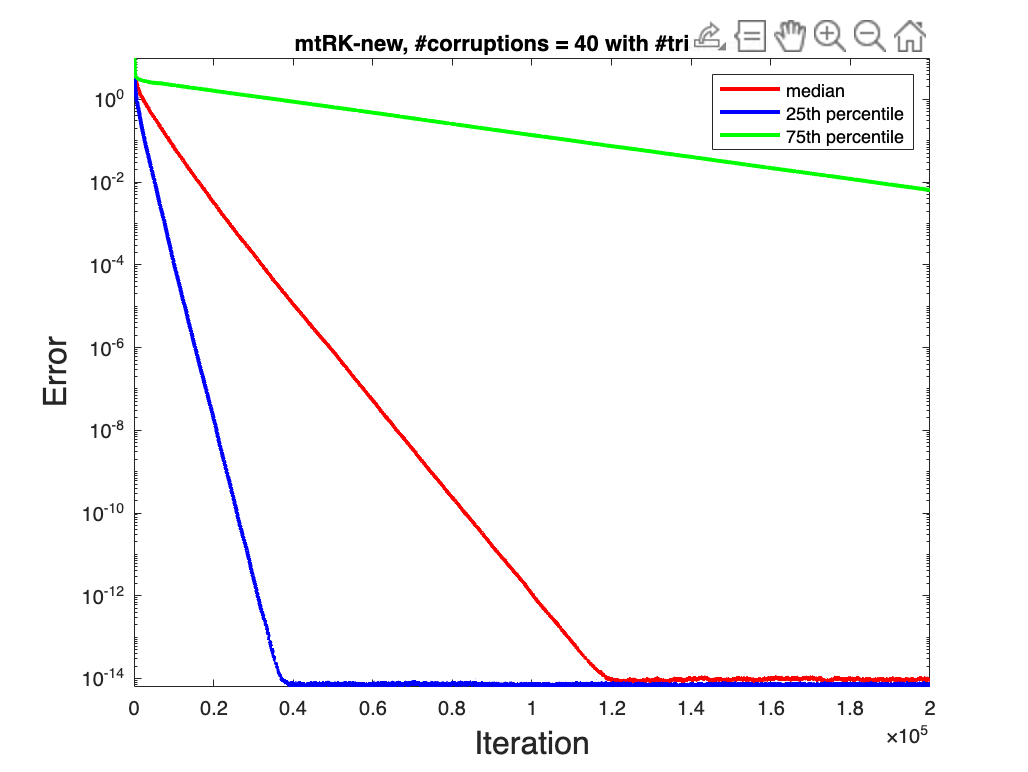

l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 40; % number of corruptions 
size_corrupt= 100; % size of corruptions 
num_its = 200000; % number of iterations

trials = 20; 
errs_matrix = zeros(trials, num_its+1);
for t = 1:trials
    %generate tensors
    A = randn(m,l,n);
    X_true = randn(l,p,n);
    B = tprod(A,X_true);
    dims = prod(size(B));
    ix_lin = randsample(dims,num_corrupt);
    [ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
    for i=1:num_corrupt
        B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt; %original
    end 
    [~,its] = mtRK_new(A,B,randn(l,p,n),num_its, num_corrupt);
    for j = 1:num_its+1
        est = its{j} - X_true;
        errs_matrix(t,j) = norm(est(:));
    end
end

semilogy(median(errs_matrix),'Linewidth',2, 'Color', 'red')
title("mtRK-new, #corruptions = " + num_corrupt + " with #trials = " + trials)
xlabel ('Iteration', FontSize=16)
ylabel('Error', FontSize=16)
axis([0 num_its 0 10])

hold on

semilogy(quantile(errs_matrix, 0.25),'Linewidth',2, 'Color', 'blue')

semilogy(quantile(errs_matrix, 0.75),'Linewidth',2, 'Color', 'green')

hold off

legend('median','25th percentile', '75th percentile');